## AAE440 HW5 MATLAB CODE

## Problem 1

#### <b>

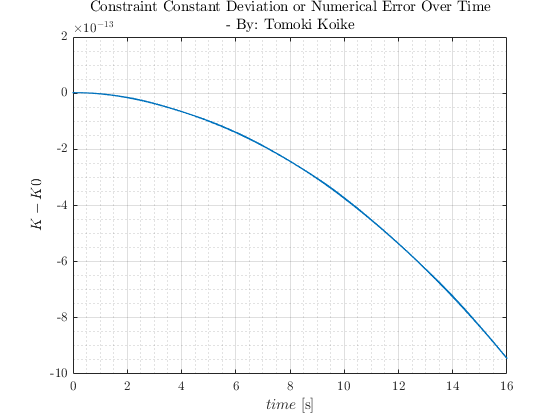

fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW5';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

% Constants
T = 40;  % Torque [N-m]
I_cm = [400 0 0; 0 100 0; 0 0 400];  % Inertia Dyadic [kg-m2]
I = 400;
J = 100;

% Initial Conditions
w0 = [1 2 1];  % Initial angular velocities [rad/s]
e0 = [0 0 0 1];  % Initial Euler Parameters
C0 = [1 0 0 0 1 0 0 0 1];  % Initial DCM

% Numerical integrations dynamic and kinematic EOMs
tspan = [0 16]; % Integration time
y0 = [w0 e0 0 C0]; % Initial conditions
option = odeset('RelTol', 1e-13, 'AbsTol', 1e-13); % Integration Tolerance
[t, res] = ode45(@(t,y) EOM(t,y,I,J,T), tspan, y0, option);
ws = res(:,1:3);  % angular velocity dot
es = res(:,4:7);  % Euler parameter dot
K_minus_K0 = res(:,8);  % K-K0
C_mats = res(:,9:end);  % DCM values 

% Plotting K-K0 against time
fig1 = figure("Renderer","painters");
plot(t, K_minus_K0)
ylabel('$K-K0$', "Interpreter","latex")
xlabel('$time$ [s]', "Interpreter","latex")
title({'Constraint Constant Deviation or Numerical Error Over Time',['- By:' ...
    ' Tomoki Koike']},"Interpreter", "latex")
grid on
grid minor
box on
saveas(fig1, fullfile(fdir, 'constraint_constant.png'));

### <c>

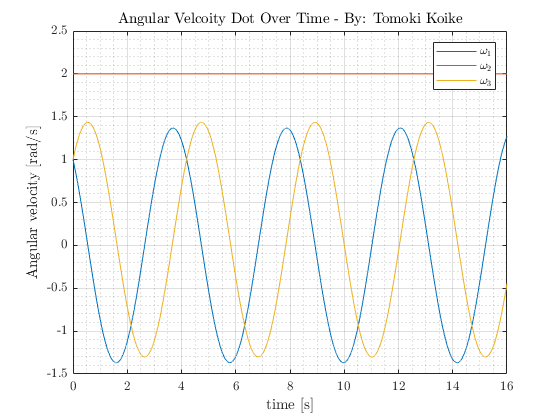

% Plotting the angular velocity 
fig2 = figure("Renderer","painters");
plot(t, ws)
ylabel('Angular velocity [rad/s]')
xlabel('time [s]')
title({'Angular Velcoity Dot Over Time - By: Tomoki Koike'})
ylim([-1.5, 2.5])
legend('$\omega_1$', '$\omega_2$', '$\omega_3$')
grid on
grid minor
box on
saveas(fig2, fullfile(fdir, 'angular_velocity.png'))

### <d>

% Define a new time span with a 2 second increment 
tspan2 = 0:0.2:50;

% conduct ode45 for differential equation 
[t2, res2] = ode45(@(t,y) EOM(t,y,I,J,T), tspan2, y0, option); 

% Assign C12, C22, and C32
C12s = res2(:,10);
C22s = res2(:,13);
C32s = res2(:,16);


% Calculating the precession and nutation using loop 
alphas = zeros([length(t2),1]);
gammas = zeros([length(t2),1]);
for n = 1:length(t2)
    % calculating and verfiying gamma
    gammas(n) = acos(C22s(n));
    if gammas(n) < 0 || gammas(n) > pi
        gammas(n) = -gammas(n);
    end
    % calculating and verfying the alpha
    alpha1 = asin(C12s(n)/sin(gammas(n)));
    alpha2 = acos(C32s(n)/sin(gammas(n)));
    if alpha1 == alpha2 || alpha1 == -alpha2
        alphas(n) = alpha1;
    elseif pi-alpha1 == alpha2 || -pi-alpha1 == alpha2
        alphas(n) = alpha2;
    else 
        alphas(n) = -alpha2;
    end  
    gammas(n) = rad2deg(gammas(n));
    alphas(n) = rad2deg(alphas(n));
end
% Define K 
K = res2(:,8) + 1;

res_array = [t2 res2(:,1:3) C12s C22s C32s alphas gammas K];
res_table = array2table(res_array, "VariableNames",{'time','omega1',['' ...
    'omega2'],'omega3','C12','C22','C32','alpha', 'gamma','K'});
writetable(res_table, fullfile(fdir, 'output_table.xlsx'));

## Problem 2

### <a>

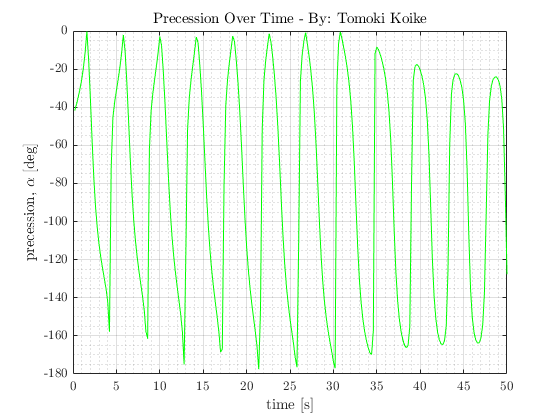

% Plotting the precession and nutation individually as a function of time 
% Precession
fig3 = figure("Renderer","painters");
plot(t2, alphas,'g')
title({'Precession Over Time - By: Tomoki Koike'})
xlabel('time [s]')
ylabel('precession, $\alpha$ [deg]')
grid on
grid minor
box on
saveas(fig3, fullfile(fdir, 'precession_vs_time.png'));

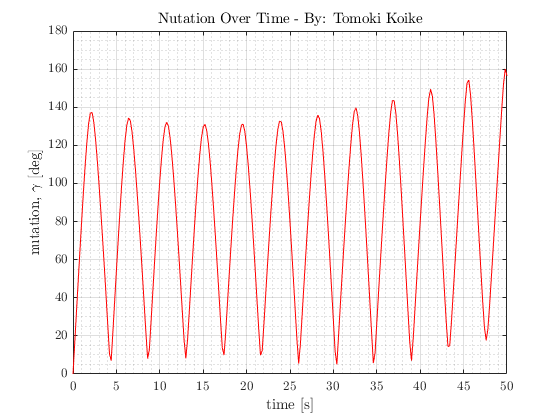

% Nutation 
fig4 = figure("Renderer","painters");
plot(t2, gammas,'r')
title({'Nutation Over Time - By: Tomoki Koike'})
xlabel('time [s]')
ylabel('nutation, $\gamma$ [deg]')
grid on
grid minor
box on
saveas(fig4, fullfile(fdir, 'nutation_vs_time.png'));

### <b>

% Do the steps in the last half of problem 1 with smaller increments of
% time span
tspan3 = 0:0.1:16;
% conduct ode45 for differential equation 
[t3, res3] = ode45(@(t,y) EOM(t,y,I,J,T), tspan3, y0, option); 
C_new = res3(:,9:17);
% Assign C12, C22, and C32
C12s_new = res3(:,10);
C22s_new = res3(:,13);
C32s_new = res3(:,16);

% Finding the index when t=0.2 and t=1.5 and corresponding C12 and C32
idx_t0p2 = find(t3==0.2);
idx_t1p5 = find(t3==1.5);
C12_t0p2 = C12s_new(idx_t0p2);
C22_t0p2 = C22s_new(idx_t0p2);
C32_t0p2 = C32s_new(idx_t0p2);
C12_t1p5 = C12s_new(idx_t1p5);
C22_t1p5 = C22s_new(idx_t1p5);
C32_t1p5 = C32s_new(idx_t1p5);

% Assigning a temporary DCM with corresponding times 
C_temp = res3([idx_t0p2 idx_t1p5], 9:end);
% calculating and verfiying gamma
[alphas_temp, gammas_temp, etas_temps] = ang_calc_body212(C_temp);

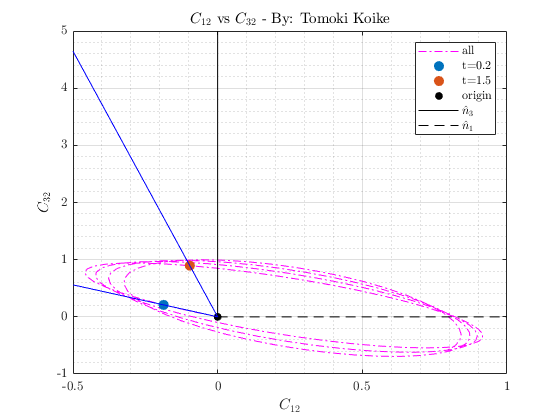

% Plots with the specific times t = 0.2 and 1.5
fig5 = figure("Renderer","painters");
plot(C12s_new, C32s_new,'-.m','MarkerSize',15)
title('$C_{12}$ vs $C_{32}$ - By: Tomoki Koike')
xlabel('$C_{12}$')
ylabel('$C_{32}$')
hold on 
plot(C12_t0p2, C32_t0p2, '.','MarkerSize',26)
plot(C12_t1p5,C32_t1p5,'.','MarkerSize',26)
plot(0,0,'.k','MarkerSize',20)
plot([0 0],[0 5],'-k')
plot([0 1],[0 0],'--k')
d = linspace(0,-0.5,100);
plot(d,d.*(C32_t0p2/C12_t0p2),'-b')
plot(d,d.*(C32_t1p5/C12_t1p5),'-b')
hold off
legend('all','t=0.2','t=1.5','origin','$\hat{n}_3$','$\hat{n}_1$')
grid on
grid minor
box on
saveas(fig5, fullfile(fdir, 'C12_vs_C32.png'));

% Calcluating h 
% @ t = 0.2
h_t0p2 = sqrt(C12_t0p2^2 + C32_t0p2^2);
gamma_est_t0p2 = asin(h_t0p2);
% @ t = 1.5
h_t1p5 = sqrt(C12_t1p5^2 + C32_t1p5^2);
gamma_est_t1p5 = asin(h_t1p5);

% Analysis 
array_temp = [C22s_new, acos(C22s_new), asin(sqrt(C12s_new.^2+C32s_new.^2)),...
    pi-asin(sqrt(C12s_new.^2+C32s_new.^2))];
table_temp = array2table(array_temp, "VariableNames",{'C22', 'gammaB', 'gammaA', 'piMinusGammaA'});
table_temp_top40 = table_temp(1:40,:)

table_temp_top40 = 40×4 table
      C22       gammaB     gammaA     piMinusGammaA
    ________    _______    _______    _____________

           1          0          0       3.1416    
     0.98997    0.14174    0.14174       2.9999    
     0.95995    0.28396    0.28396       2.8576    
     0.91045    0.42643    0.42643       2.7152    
      0.8425    0.56888    0.56888       2.5727    
      0.7577    0.71102    0.71102       2.4306    
     0.65807    0.85254    0.85254       2.2891    
      0.5461     0.9931     0.9931       2.1485    
     0.42458     1.1323     1.1323       2.0093    
     0.29654     1.2697     1.2697       1.8719    
     0.16514     1.4049     1.4049       1.7367    
    0.033577     1.5372     1.5372       1.6044    
    -0.09505      1.666     1.4756        1.666    
    -0.21781     1.7904     1.3512       1.7904    
 

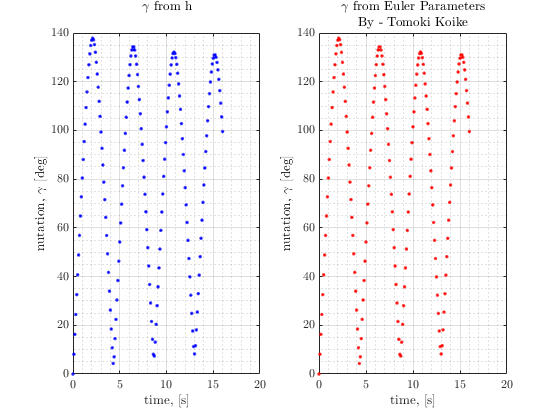

% Actually calculating gamma with h 
gammas_h = calc_gamma_with_h(C12s_new, C22s_new, C32s_new);
gammas_h = rad2deg(gammas_h);
% The actual gammas from the Euler parameters
[alpha_eulers, gammas_eulers, etas_eulers] = ang_calc_body212(C_new);
fig6 = figure("Renderer","painters");
subplot(1,2,1)
plot(t3, gammas_h,'.b')
title({'$\gamma$ from h',''})
xlabel('time, [s]')
ylabel('nutation, $\gamma$ [deg]')
grid on
grid minor
box on
subplot(1,2,2)
plot(t3, gammas_eulers, '.r')
title({'$\gamma$ from Euler Parameters','By - Tomoki Koike'})
xlabel('time, [s]')
ylabel('nutation, $\gamma$ [deg]')
grid on 
grid minor
box on
saveas(fig6, fullfile(fdir, 'gammas_with_h_and_euler.png'))

### <c>

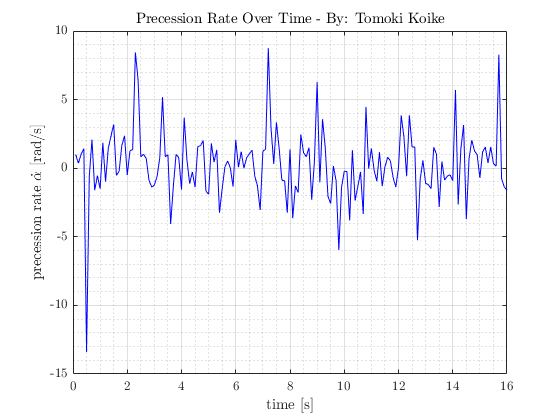

% Do the steps in the last half of problem 1 with smaller increments of
% time span
tspan_c = 0:0.1:16;
% conduct ode45 for differential equation 
[t_c, res_c] = ode45(@(t,y) EOM(t,y,I,J,T), tspan_c, y0, option); 
% Assign C12, C22, and C32
C_c = res_c(:,9:end);
w1 = res_c(:,1);
w2 = res_c(:,2);
w3 = res_c(:,3);
[alpha_c, gamma_c, eta_c] = ang_calc_body212(C_c);

% Calculating precession rate
alpha_dot = (w1.*sin(eta_c) - w3.*cos(eta_c)) ./ sin(gamma_c);

% Plotting
fig7 = figure('Renderer',"painters");
plot(t_c, alpha_dot,'-b')
title('Precession Rate Over Time - By: Tomoki Koike',"Interpreter","latex")
xlabel('time [s]',"Interpreter","latex")
ylabel('precession rate $\dot{\alpha}$ [rad/s]',"Interpreter","latex")
grid on
grid minor
box on
saveas(fig7, fullfile(fdir,'precession_rate.png'));

### <d>

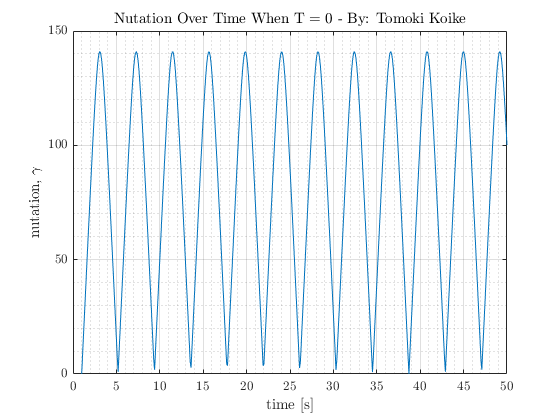

% Constants
tspan_d = 1:0.1:50;
T_d1 = 0;  % Torque [N-m]
[t_d1, res_d1] = ode45(@(t,y) EOM(t,y,I,J,T_d1), tspan_d, y0, option); 
C_d1 = res_d1(:,9:end);
[alpha_d1, gamma_d1, eta_d1] = ang_calc_body212(C_d1);

T_d2 = 180; 
[t_d2, res_d2] = ode45(@(t,y) EOM(t,y,I,J,T_d2), tspan_d, y0, option); 
C_d2 = res_d2(:,9:end);
[alpha_d2, gamma_d2, eta_d2] = ang_calc_body212(C_d2);

% Plotting 
fig8 = figure("Renderer","painters");
plot(t_d1, gamma_d1)
xlabel('time [s]', "Interpreter","latex")
ylabel('nutation, $\gamma$', "Interpreter","latex")
title('Nutation Over Time When T = 0 - By: Tomoki Koike',"Interpreter","latex")
grid on
grid minor 
box on
saveas(fig8, fullfile(fdir,'gamma_t_equal_0.png'));

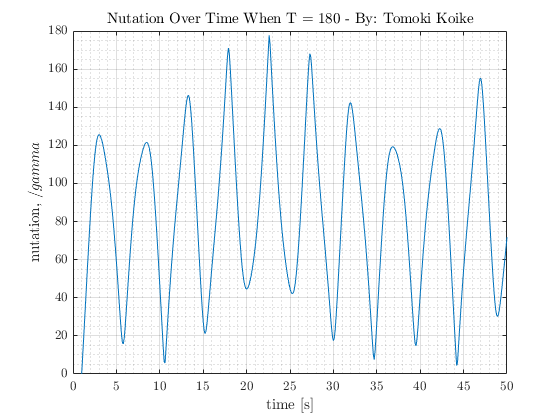


fig9 = figure("Renderer","painters");
plot(t_d2, gamma_d2)
xlabel('time [s]',"Interpreter","latex")
ylabel('nutation, $/gamma$',"Interpreter","latex")
title('Nutation Over Time When T = 180 - By: Tomoki Koike',"Interpreter","latex")
grid on 
grid minor
box on
saveas(fig9, fullfile(fdir,'gamma_t_equal_180.png'));

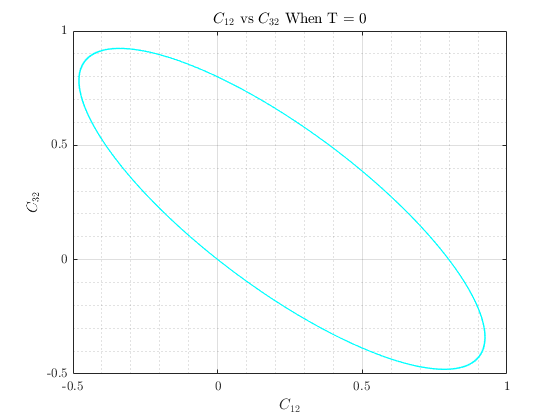


fig10 = figure("Renderer","painters");
plot(C_d1(:,2), C_d1(:,8), '-c')
title('$C_{12}$ vs $C_{32}$ When T = 0',"Interpreter","latex")
xlabel('$C_{12}$',"Interpreter","latex")
ylabel('$C_{32}$',"Interpreter","latex")
grid on 
grid minor 
box on 
saveas(fig10, fullfile(fdir,'C12_C32_T0.png'))

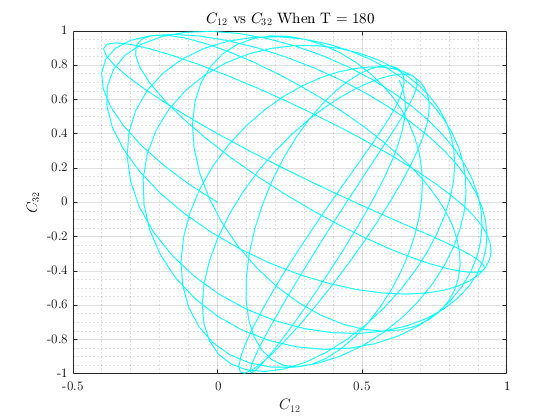


fig11 = figure('Renderer',"painters");
plot(C_d2(:,2), C_d2(:,8), '-c')
title('$C_{12}$ vs $C_{32}$ When T = 180',"Interpreter","latex")
xlabel('$C_{12}$',"Interpreter","latex")
ylabel('$C_{32}$',"Interpreter","latex")
grid on 
grid minor 
box on 
saveas(fig11, fullfile(fdir,'C12_C32_T180.png'))

### Functions 

function [alphas, gammas, etas] = ang_calc_body212(DCM)
    % DCM is 1 by 9 matrix with each column being C_ij
    C12s = DCM(:,2);
    C21s = DCM(:,4);
    C22s = DCM(:,5);
    C23s = DCM(:,6);
    C32s = DCM(:,8);
    
    alphas = zeros([length(C12s),1]);
    gammas = zeros([length(C12s),1]);
    etas = zeros([length(C12s),1]);
    
    for n = 1:length(alphas)
        % calculating and verfiying gamma
        gammas(n) = acos(C22s(n));
        if gammas(n) < 0 || gammas(n) > pi
            gammas(n) = -gammas(n);
        end
        % calculating and verfying the alpha
        alpha1 = asin(C12s(n)/sin(gammas(n)));
        alpha2 = acos(C32s(n)/sin(gammas(n)));
        if alpha1 == alpha2 || alpha1 == -alpha2
            alphas(n) = alpha1;
        elseif pi-alpha1 == alpha2 || -pi-alpha1 == alpha2
            alphas(n) = alpha2;
        else 
            alphas(n) = -alpha2;
        end  
        eta1 = asin(C21s(n)/sin(gammas(n)));
        eta2 = acos(-C23s(n)/sin(gammas(n)));
        if eta1 == eta2 || eta1 == -eta2
            etas(n) = eta1;
        elseif pi-eta1 == eta2 || -pi-eta1 == eta2
            etas(n) = eta2;
        else 
            etas(n) = -eta2;
        end  
        gammas(n) = rad2deg(gammas(n));
        alphas(n) = rad2deg(alphas(n));
        etas(n) = rad2deg(etas(n));
    end
end

function ang = eval_cos(theta)
    if theta < 0 || theta > pi
        ang = -theta;
    else
        ang = theta;
    end
end

function ang = eval_sin(theta)
    if -pi/2 <= theta && theta <= pi/2
        ang = theta;
    else
        ang = -theta;
    end
end

function gamma = calc_gamma_with_h(C12, C22, C32)
    h = asin(sqrt(C12.^2 + C32.^2));
    gamma = zeros([length(h), 1]);
    for x = 1:length(h)
        if C22(x) > 0 
            gamma(x) = h(x);
        elseif C22(x) < 0
            gamma(x) = pi - h(x);
        end
    end
end